# Function for presentation: TumorRed

clc; clear all; close all;
A = imageDatastore('Final Project Images\Training\Group1\');
M = datastore('Final Project Images\Training\Group2\');
PT = datastore('Final Project Images\Training\Group3\');

Creates 3 image datastores for the 3 types of tumor.

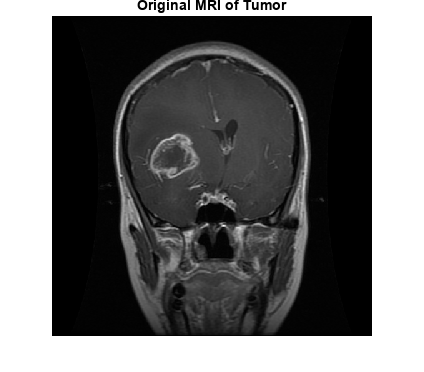

TestImage = readimage(A,15);
imshow(TestImage);
title('Original MRI of Tumor');

xlim([1 513])
ylim([1 513])

Initializes a test image for the purposes of the demonstration

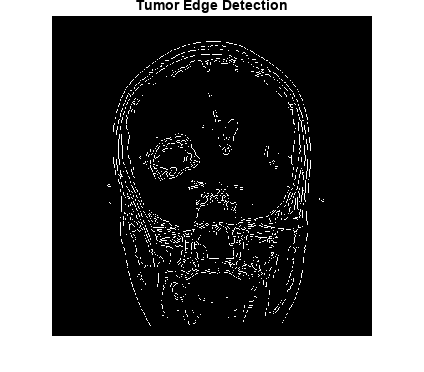

InitialImage = double(TestImage);
InitialImage = InitialImage./max(max(InitialImage));

[~,Thresh] = edge(TestImage,'sobel');
FudgeFactor= 0.75;
ImageEdge = edge(TestImage,'sobel',FudgeFactor*Thresh);
imshow(ImageEdge)
title('Tumor Edge Detection');

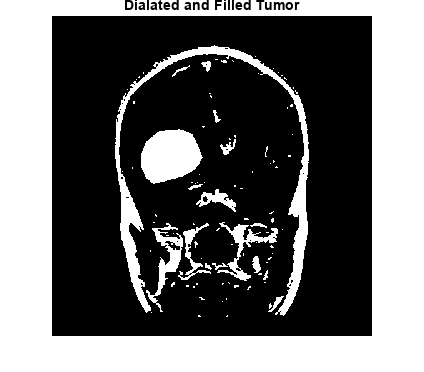


level = graythresh(TestImage);
I = im2bw(TestImage, level+0.175);
load('2652.mat');
TumorMask = cjdata.tumorMask;
TumorPoints = find(I ~= TumorMask);
I(TumorPoints) = 1;
imshow(I);
title('Dialated and Filled Tumor');

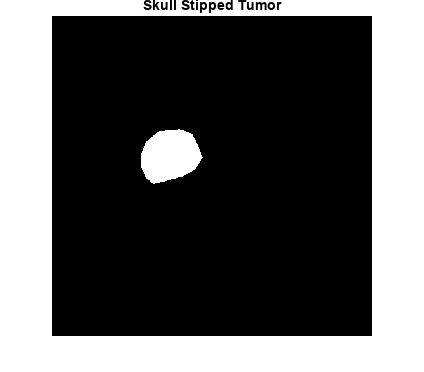


BinaryImage = bwareaopen(I, 10);
BinaryImage(end,:) = true;
BinaryImage = imfill(BinaryImage, 'holes');
se = strel('disk', 10, 0);
BinaryImage = imerode(BinaryImage, se);
SkullStripImage = I;
SkullStripImage(~BinaryImage) = 0;
imshow(TumorMask);
title('Skull Stipped Tumor');

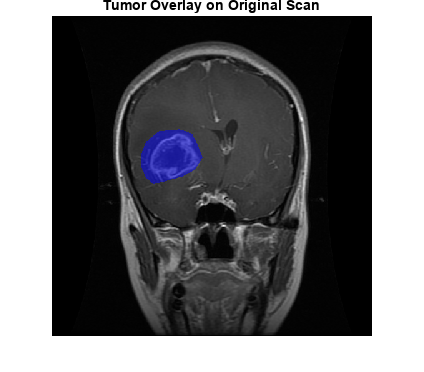


imshow(labeloverlay(TestImage, TumorMask));
title('Tumor Overlay on Original Scan');


[i, j] = find(TumorMask == 1);
MiddlePoint = round(length(i)/2);
Distance = round(sqrt((i(MiddlePoint)-1)^2+(j(MiddlePoint)-1)^2));
display(Distance);

Distance = 319

Strips the Image of all features except the tumor. Also calculates the distance from the center of the tumor to the left most edge of the scan.